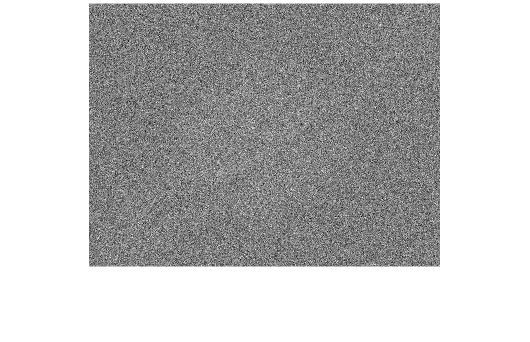

clear all;
% EX 1. Image smoothing
load('noisy.mat');

imshow(noisy,[]);

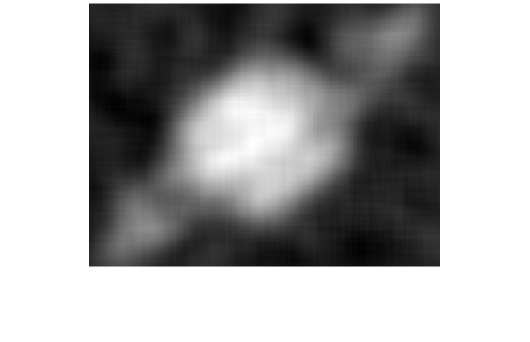


g_sigma = 20;

filtersize = g_sigma * 3;

g = fspecial('gaussian', filtersize, g_sigma);
filtim = filter2(g, noisy);

imshow(filtim,[])

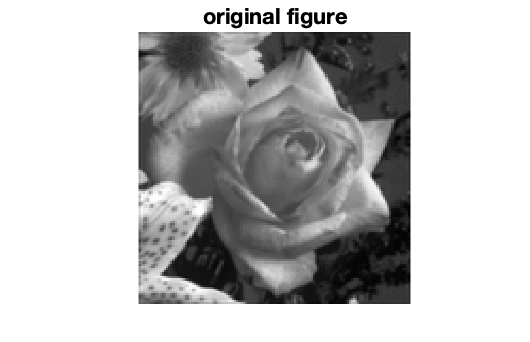

% EX 2. Unsharp masking; high-pass filtering; high-boost filtering

flower = double(imread('flower.tif'));
imshow(flower,[], 'InitialMagnification', 'fit');
title('original figure');

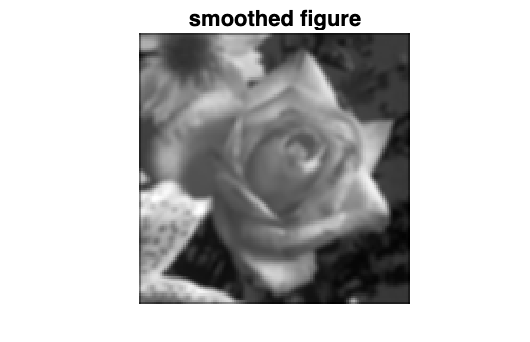


g2 =  fspecial('average',3);
flower_smoothed = filter2(g2, flower);
imshow(flower_smoothed,[], 'InitialMagnification', 'fit');
title('smoothed figure');

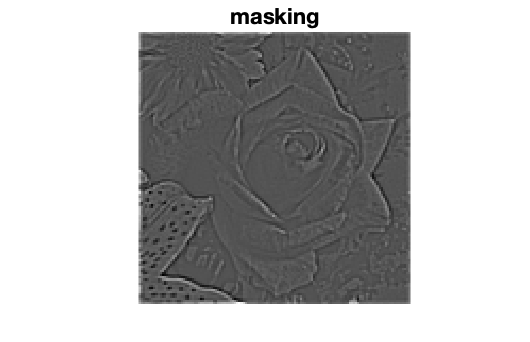


mask = flower - flower_smoothed;
imshow(mask,[], 'InitialMagnification', 'fit');
title('masking');


% A is an adjustable parameter
A = 1

A = 1

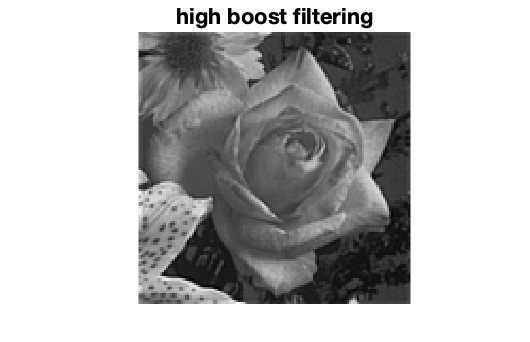


flower_high_boost = flower + A .* mask;
imshow(flower_high_boost,[], 'InitialMagnification', 'fit');
title('high boost filtering');

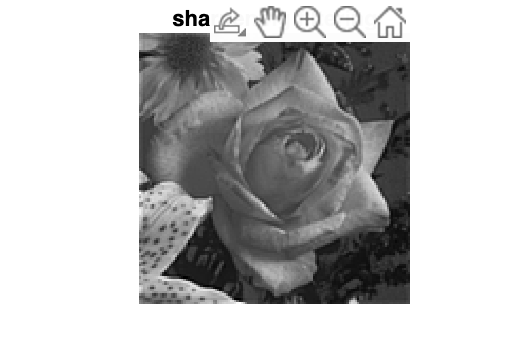

% EX 3. High-pass filtering – computed as a convolution
hp = (1/9) .* [-1 -1 -1; -1 8 -1; -1 -1 -1];

flower_convolved = filter2(hp, flower);

flower_sharpening = flower + flower_convolved;
imshow(flower_sharpening,[], 'InitialMagnification', 'fit');
title('sharpening filtering');

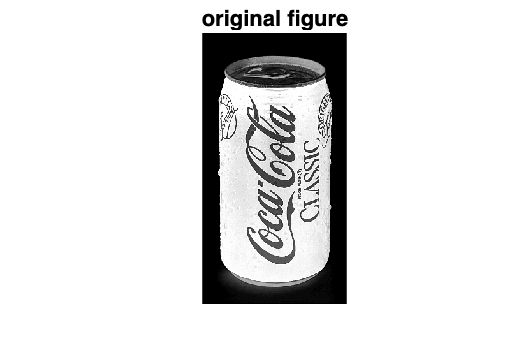

% EX 4. Edge Detection
load('coke2.mat');
imshow(coke,[], 'InitialMagnification', 'fit');
title('original figure');


% Create the Sobel filters
sbh=[1 2 1; 0 0 0; -1 -2 -1] % horizontal direction

sbh =      1     2     1
     0     0     0
    -1    -2    -1


sbv=[1 0 -1; 2 0 -2; 1 0 -1] % vertical direction

sbv =      1     0    -1
     2     0    -2
     1     0    -1


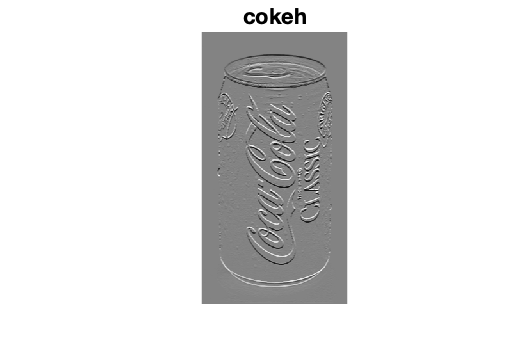


cokeh = filter2(sbh, coke);
imshow(cokeh,[], 'InitialMagnification', 'fit');
title('cokeh');

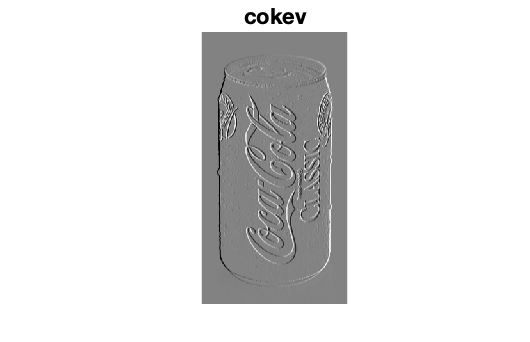


cokev = filter2(sbv, coke);
imshow(cokev,[], 'InitialMagnification', 'fit');
title('cokev');

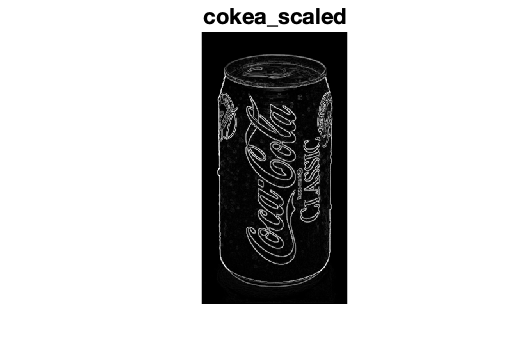


cokea=abs(cokeh) + abs(cokev);
cokea_scaled = cokea / max(max(cokea)).* 256;
imshow(uint8(cokea_scaled),[], 'InitialMagnification', 'fit');
title('cokea\_scaled');

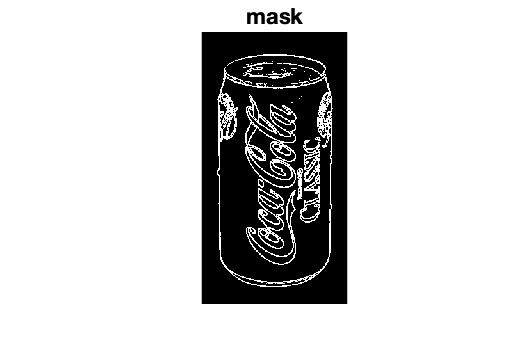


%imhist(uint8(cokea_scaled));

mask = im2bw(cokea_scaled/256., 50/256);
imshow(uint8(mask*255),[], 'InitialMagnification', 'fit');
title('mask');